# Волатильность RUONIA вокруг решений по ключевой ставке

Файлы: ruonia.xlsx (Date, Value), decisions.xlsx (Date, Extra, RateNew, Consensus, EffDate), reserves.xlsx (график периодов усреднения обязательных резервов с сайта ЦБ, cbr.ru/oper_br/oap).

С 2027 г. новая ключевая ставка будет вступать в силу не с ближайшего понедельника, а с ближайшей среды — чтобы совпадать с началом периода усреднения обязательных резервов (будут изменены по всей видимости). 

Заявленная цель ЦБ — снизить волатильность ставок денежного рынка. Проверяем, где эта волатильность сейчас и от чего зависит.

clear; clc; close all;
rng(20260901);

SUNNY = ['#0051CA'; '#F8AC27'; '#3F863F';'#C6DBA1'; '#FDD65F'; '#FBEEBD'; '#50766E'];
mymap = sscanf(SUNNY','#%2x%2x%2x',[3,size(SUNNY,1)]).' / 255;
LINK_STR   = '@CBRSunnyMorning';

## 1. Данные

Торговый календарь задаёт сам файл RUONIA: какие даты в нём есть, те и рабочие. Выходные по календарю не выбрасываем — в выборке есть перенесённые рабочие субботы, RUONIA в них считается.

R = readtable('ruonia.xlsx');
R.Properties.VariableNames(1:2) = {'Date','RUONIA'};
R = sortrows(R,'Date');  
R = R(~isnan(R.RUONIA), :);
if any(diff(R.Date) <= 0), error('Повторяющиеся даты в ruonia.xlsx'); end

D = readtable('decisions.xlsx');
D.Extra = logical(D.Extra);
D = sortrows(D,'Date');

% Шаг и тип решения
D.Delta = [0; round((D.RateNew(2:end)-D.RateNew(1:end-1))*100)];
D.Type  = repmat("hold",height(D),1);
D.Type(D.Delta<0) = "cut";  D.Type(D.Delta>0) = "hike";

% ЗНАК СЮРПРИЗА.
D.Surprise    = (D.RateNew - D.Consensus)*100;
D.AbsSurprise = abs(D.Surprise);

% График периодов усреднения обязательных резервов.
% Структура: Start–End — сам период (начало ВСЕГДА среда, конец вторник,
% длительность 28 или 35 дней, периоды идут встык); отчётный период —
% календарный месяц, по которому посчитан объём (он зафиксирован задолго до
% начала усреднения и от ставки не зависит); Start_reg–End_reg — 2-3 дня
% регулирования в середине месяца, техническая сверка.
M = readtable('reserves.xlsx');
M.Properties.VariableNames(1:6) = {'Start','End','Days','RepPeriod','StartReg','EndReg'};
M = M(~isnat(M.Start), :);
M = sortrows(M,'End');

fprintf('Периодов усреднения: %d, %s — %s. Начало в среду: %d из %d\n', ...
    height(M), datestr(M.Start(1),'dd.mm.yyyy'), datestr(M.End(end),'dd.mm.yyyy'), ...
    sum(weekday(M.Start)==4), height(M));

Периодов усреднения: 72, 13.01.2021 — 12.01.2027. Начало в среду: 72 из 72



fprintf('RUONIA: %d наблюдений, %s — %s\n', height(R), ...
    datestr(R.Date(1),'dd.mm.yyyy'), datestr(R.Date(end),'dd.mm.yyyy'));

RUONIA: 1367 наблюдений, 11.01.2021 — 27.08.2026


fprintf('Заседаний: %d (плановых %d, внеплановых %d), с ненулевым сюрпризом %d\n', ...
    height(D), sum(~D.Extra), sum(D.Extra), sum(D.AbsSurprise>0));

Заседаний: 49 (плановых 45, внеплановых 4), с ненулевым сюрпризом 17


## 2. Спред к ДЕЙСТВУЮЩЕЙ ключевой ставке

ПОЧЕМУ спред, а не сама RUONIA: ставка меняется в дату вступления в силу, и по сырой RUONIA в этот день будет механический скачок на величину шага — до 1050 б.п. в феврале 2022 г. Это не волатильность рынка.

ПОЧЕМУ EffDate, а не дата заседания: у плановых решений ставка начинает действовать в ближайший понедельник, у внеплановых — в тот же или на следующий день. В decisions.xlsx EffDate задана явно, в том числе вручную для внеплановых.

if D.Delta(1) ~= 0
    warning(['Первое решение — изменение на %+d б.п. Подстановка этого ' ...
        'уровня назад неверна. Обрежьте RUONIA по первой EffDate или ' ...
        'добавьте предыдущий уровень ставки.'], D.Delta(1));
end
R.KeyRate = stepSeries(R.Date, D.EffDate, D.RateNew);
R.Spread  = (R.RUONIA - R.KeyRate)*100;
fprintf('Спред: первое значение %+.0f б.п., среднее %+.1f б.п.\n', ...
    R.Spread(1), mean(R.Spread,'omitnan'));

Спред: первое значение +2 б.п., среднее -20.2 б.п.


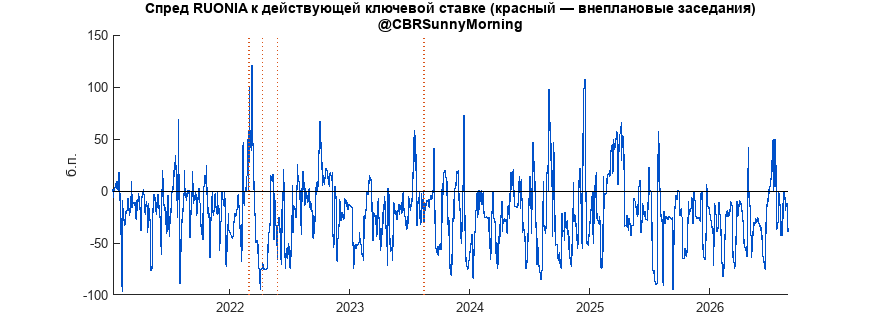


close all
figure('Color','w','Position',[60 60 1000 380]);
plot(R.Date, R.Spread, 'LineWidth',0.9, 'Color',mymap(1,:)); hold on;
yl = ylim;
for i = find(D.Extra)'
    plot([D.EffDate(i) D.EffDate(i)], yl, ':', 'Color',[.85 .33 .10], 'LineWidth',1.2);
end
plot(R.Date([1 end]),[0 0],'k-'); 
ylim(yl);
ylabel('б.п.'); 
box off;
title(["Спред RUONIA к действующей ключевой ставке (красный — внеплановые заседания)";LINK_STR]);

## 2b. Метрика Банка России и сверка с опубликованными числами

ЦБ измеряет волатильность как СКО спреда RUONIA к ключевой ставке в б.п. и публикует её в ОНЕГДКП. 

Прогоняем свой расчёт по тем же периодам: если числа сходятся, значит пайплайн считает ровно то же, что регулятор

ref = {  '2023 год',      datetime(2023,1,1),  datetime(2023,12,31), -23,  28
    'янв-сен 2024',  datetime(2024,1,1),  datetime(2024,9,30),  -23,  33
    '2025 год',      datetime(2025,1,1),  datetime(2025,12,31), NaN,  37
    'янв-июл 2026',  datetime(2026,1,1),  datetime(2026,7,31),  -28,  28 };
fprintf('\n%-14s %18s %18s\n','Период','наше (сред/СКО)','ЦБ (сред/СКО)');

Период            наше (сред/СКО)      ЦБ (сред/СКО)


for i = 1:size(ref,1)
    m = R.Date >= ref{i,2} & R.Date <= ref{i,3};
    if ~any(m), continue; end
    fprintf('%-14s %8.0f %9.0f %8s %9.0f\n', ref{i,1}, mean(R.Spread(m),'omitnan'), ...
        std(R.Spread(m),'omitnan'), ternary(isnan(ref{i,4}),'—',sprintf('%.0f',ref{i,4})), ref{i,5});
end

2023 год            -23        28      -23        28
янв-сен 2024        -23        33      -23        33
2025 год            -17        35        —        37
янв-июл 2026        -28        28      -28        28


## 3. Мера волатильности

Прокси — `Δспреда` день ко дню. Она не зависит от уровня спреда и не заражена скачком ставки. 

Логарифм — потому что распределение скошено вправо; пол 0.1 б.п. защищает от log(0).

R.Vol = [NaN; abs(diff(R.Spread))];
w = R.Vol;  w(w < 0.1) = 0.1;  R.LogVol = log(w);
fprintf('|Δспреда|: медиана %.1f б.п., среднее %.1f б.п.\n', ...
    median(R.Vol,'omitnan'), mean(R.Vol,'omitnan'));

|Δспреда|: медиана 6.0 б.п., среднее 11.2 б.п.


## 4. Локальный фон: адаптивное предсобытийное окно

Мера события: AV = log(vol) в ядре [0..+2] МИНУС средняя log(vol) в локальном окне перед ЭТИМ ЖЕ заседанием. Результат читается как «во сколько раз выше собственного фона», 1.00 = ничего не произошло.

ПОЧЕМУ локальный фон: в 2022 г. фоновая волатильность сама была в разы выше, чем в 2024 г. Сравнение с общим средним по выборке дало бы «рост» у любого события турбулентного года автоматически.

ДАЛЬНИЙ КРАЙ. Фон не должен захватывать всплеск предыдущего заседания. Медианный интервал между заседаниями 29 торговых дней, но минимальный — 9 (внеплановое 26.05.2022 и плановое 10.06.2022). Фиксированной глубиной это не решается: при -30 фон задевает чужое окно у 37 заседаний из 49, при -18 всё ещё у 7, а урезание до -15 не помогает вообще. Поэтому глубина -30, но дни влияния ЛЮБОГО другого заседания из окна вырезаются. Если осталось меньше minBase дней — окно углубляется.

БЛИЖНИЙ КРАЙ = -(лаг заседание->вступление) - 2. Сейчас лаг 1 торговый день, край -3. С 2027 г. лаг станет 3 дня и край сам уедет на -5. Дальше отступать не нужно — секция 6 это проверяет, а каждый выброшенный день только зашумляет фон и снижает мощность.

cfg.far      = -30;    % стартовая глубина окна
cfg.otherWin = -1:3;   % дни влияния чужого заседания
cfg.minBase  = 10;     % минимум дней в фоне
cfg.hit      = [0 1 2];% ядро окна события
cfg.tau      = -5:5;   % окно для профиля
cfg.minShift = 10;     % минимальная ротация календаря, торговых дней
cfg.nPerm    = 20000;  % перестановок ярлыков

D.iEff = mapToCal(D.EffDate, R.Date);
D.iAnn = mapToCal(D.Date,    R.Date);
cfg.near = -(mode(D.iEff - D.iAnn) + 2);

allE = sort(D.iEff(~isnan(D.iEff)));
[baseOffs, nUsed] = baselineOffsets(D.iEff, allE, cfg, height(R));
fprintf('Фон [%d..%d] минус соседи: дней мин %d, медиана %d\n', ...
    cfg.far, cfg.near, min(nUsed), round(median(nUsed)));

Фон [-30..-3] минус соседи: дней мин 18, медиана 23



[AV, D.AV]     = avEvents(R.LogVol, D.iEff, baseOffs, cfg.tau, cfg.hit);
[~,  D.AVann]  = avEvents(R.LogVol, D.iAnn, baseOffs, cfg.tau, cfg.hit);
sched = ~D.Extra;

## 5. Профиль по типам решений

при СОХРАНЕНИИ ставки всплеска нет вообще,

почти весь эффект сидит в ОДНОМ дне — в дате вступления ставки в силу.

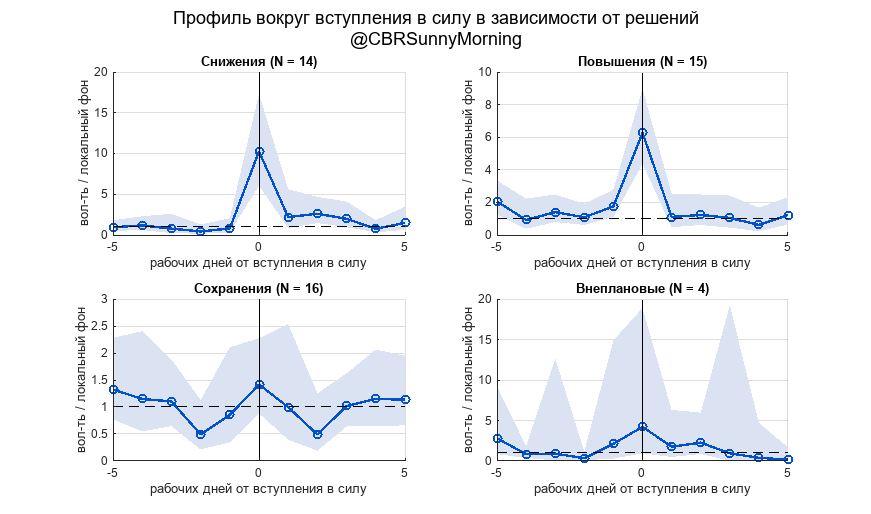

names = {'Снижения','Повышения','Сохранения','Внеплановые'};
masks = {sched & D.Type=="cut", sched & D.Type=="hike", ...
    sched & D.Type=="hold", D.Extra};
figure('Color','w','Position',[60 60 1050 620]);
for g = 1:4
    subplot(2,2,g);
    A = AV(masks{g},:);
    mu = mean(A,1,'omitnan');
    se = std(A,0,1,'omitnan') ./ sqrt(sum(~isnan(A),1));
    fill([cfg.tau fliplr(cfg.tau)], exp([mu-1.96*se fliplr(mu+1.96*se)]), ...
        [.86 .89 .95],'EdgeColor','none'); hold on;
    plot(cfg.tau, exp(mu), '-o','LineWidth',1.8,'Color',mymap(1,:));
    plot(cfg.tau([1 end]),[1 1],'k--'); 
    plot([0 0],ylim,'k-');
    xlabel('рабочих дней от вступления в силу'); ylabel('вол-ть / локальный фон');
    title(sprintf('%s (N = %d)', names{g}, sum(masks{g}))); grid on; box off;
end
sgtitle(["Профиль вокруг вступления в силу в зависимости от решений";LINK_STR]);

## 5b. Календарь усреднения резервов

Внутри периода усреднения дни взаимозаменяемы: банк обязан выйти на среднее, а не на ежедневный остаток. Это делает переброску резервов между днями возможной — и именно поэтому смена ключевой ставки внутри периода создаёт стимул перекладываться. 

Между периодами переброски нет: недобор одного периода перебором следующего не закрывается.

Первое, что надо посмотреть — есть ли у самого периода собственный календарный эффект. Если есть, его надо держать в голове как конкурирующее объяснение всплесков.

iStart = mapToCal(M.Start, R.Date);
iEnd   = mapToCal(M.End,   R.Date);
mEnd   = false(height(R),1);  mStart = false(height(R),1);
for i = 1:height(M)
    if ~isnan(iEnd(i)),   mEnd(clip(iEnd(i)+(-1:0), height(R)))   = true; end
    if ~isnan(iStart(i)), mStart(clip(iStart(i)+(0:1), height(R))) = true; end
end
fprintf('|Δспреда|: последние 2 дня ПУ %.1f б.п., первые 2 дня %.1f, прочие %.1f\n', ...
    mean(R.Vol(mEnd),'omitnan'), mean(R.Vol(mStart),'omitnan'), ...
    mean(R.Vol(~mEnd & ~mStart),'omitnan'));

|Δспреда|: последние 2 дня ПУ 19.2 б.п., первые 2 дня 15.5, прочие 9.7



% Позиция каждого решения внутри периода усреднения: 0 = самое начало,
% 1 = самый конец. Считаем и для фактической даты вступления в силу
% (понедельник), и для гипотетической среды по правилу с 2027 г.
D.EffWed = D.Date + days(mod(3 - weekday(D.Date), 7));   % ближайшая среда ПОСЛЕ
D.EffWed(D.EffWed <= D.Date) = D.EffWed(D.EffWed <= D.Date) + days(7);
D.puFrac  = periodPos(D.EffDate, M);
D.wedFrac = periodPos(D.EffWed,  M);

fprintf('Позиция вступления ставки в силу внутри ПУ (плановые):\n');

Позиция вступления ставки в силу внутри ПУ (плановые):


fprintf('  сейчас, понедельник: %.2f от длины периода\n', mean(D.puFrac(sched),'omitnan'));

  сейчас, понедельник: 0.43 от длины периода


fprintf('  правило-2027, среда: %.2f\n', mean(D.wedFrac(sched),'omitnan'));

  правило-2027, среда: 0.46


fprintf('  попадает ровно на 1-й день ПУ: сейчас %d, по новому правилу %d из %d\n', ...
    sum(D.puFrac(sched) <= 1/31), sum(D.wedFrac(sched) <= 1/31), sum(sched));

  попадает ровно на 1-й день ПУ: сейчас 0, по новому правилу 0 из 45


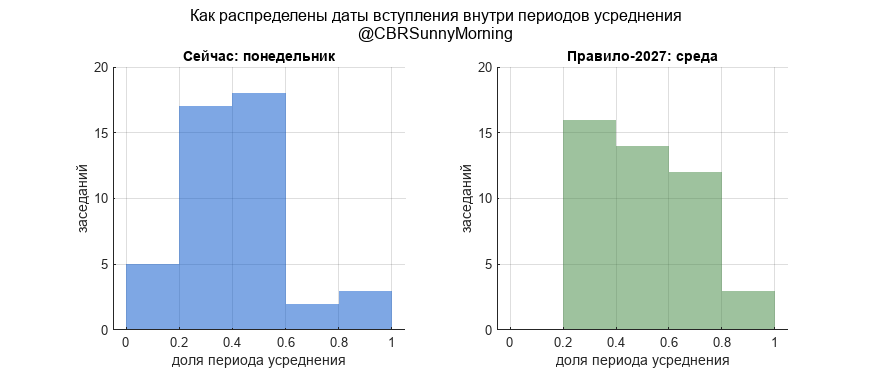


close all
figure('Color','w','Position',[60 60 900 380]);
subplot(1,2,1);
histogram(D.puFrac(sched),0:0.2:1,'FaceColor',mymap(1,:),'FaceAlpha',0.5,'EdgeColor','none');
xlabel('доля периода усреднения'); ylabel('заседаний');
title('Сейчас: понедельник'); grid on; box off; ylim([0 20]);
subplot(1,2,2);
histogram(D.wedFrac(sched),0:0.2:1,'FaceColor',mymap(3,:),'FaceAlpha',0.5,'EdgeColor','none');
xlabel('доля периода усреднения'); ylabel('заседаний');
title('Правило-2027: среда'); grid on; box off; ylim([0 20]);
sgtitle(["Как распределены даты вступления внутри периодов усреднения";LINK_STR]);

## 5c. Уровень периода усреднения — единица счёта Банка России

ЦБ формулирует операционную цель по периодам усреднения: средний за ПУ спред RUONIA к ключевой ставке по модулю не должен превышать 25 б.п. 

Поэтому главный результат надо считать в этих же единицах, а нашу дневную аномальную волатильность держать вторым слоем — она отвечает на другой вопрос («что творится вокруг конкретного заседания»), но сама по себе с показателями ЦБ не сопоставляется.

P = table();
P.Start = M.Start;  P.End = M.End;  P.Days = M.Days;
P.AvgSpread = nan(height(M),1);  P.SdSpread = nan(height(M),1);
P.nObs = zeros(height(M),1);  P.HasChange = false(height(M),1);
P.Pos = nan(height(M),1);  P.Step = zeros(height(M),1);
for i = 1:height(M)
    m = R.Date >= M.Start(i) & R.Date <= M.End(i);
    P.nObs(i) = sum(m);
    if sum(m) < 10, continue; end
    P.AvgSpread(i) = mean(R.Spread(m),'omitnan');
    P.SdSpread(i)  = std(R.Spread(m),'omitnan');
    ch = find(D.EffDate >= M.Start(i) & D.EffDate <= M.End(i) & D.Delta ~= 0);
    if ~isempty(ch)
        [~, k] = max(abs(D.Delta(ch)));  k = ch(k);
        P.HasChange(i) = true;
        P.Pos(i)  = (days(D.EffDate(k) - M.Start(i)) + 1) / M.Days(i);
        P.Step(i) = abs(D.Delta(k));
    end
end
P = P(P.nObs >= 10, :);

fprintf('\nПериодов усреднения с данными: %d\n', height(P));


Периодов усреднения с данными: 68


fprintf('Доля ПУ, пробивающих операционный порог |ср. спред| > 25 б.п.: %.0f%%\n', ...
    100*mean(abs(P.AvgSpread) > 25));

Доля ПУ, пробивающих операционный порог |ср. спред| > 25 б.п.: 44%


fprintf('\n%-24s %4s %12s %14s %10s\n','','N','|ср.спред|','СКО внутри ПУ','>25 б.п.');

                            N   |ср.спред|  СКО внутри ПУ   >25 б.п.


for k = [0 1]
    m = P.HasChange == logical(k);
    fprintf('%-24s %4d %12.1f %14.1f %9.0f%%\n', ...
        ternary(k==1,'ПУ СО сменой ставки','ПУ БЕЗ смены ставки'), sum(m), ...
        mean(abs(P.AvgSpread(m))), mean(P.SdSpread(m)), 100*mean(abs(P.AvgSpread(m))>25));
end

ПУ БЕЗ смены ставки        37         22.1           18.7        41%
ПУ СО сменой ставки        31         25.8           28.4        48%



% Тест на разницу — не t-тестом, а той же ротацией календаря заседаний.
% Прокручиваем календарь, заново определяем, в какие ПУ попали псевдо-решения,
% и смотрим распределение разницы СКО. Нулевой мир согласован с дневным тестом.
obsDiff = mean(P.SdSpread(P.HasChange)) - mean(P.SdSpread(~P.HasChange));
iSch2 = D.iEff(sched);
L0 = 1;  
L1 = height(R);  
L = L1 - L0 + 1;
rots2 = 0:L-1;  
rots2 = rots2(min(rots2, L-rots2) >= cfg.minShift);
nullD = nan(numel(rots2),1);
for k = 1:numel(rots2)
    pos = L0 + mod(iSch2 - L0 + rots2(k), L);
    fake = R.Date(pos);
    hc = false(height(P),1);
    for i = 1:height(P)
        hc(i) = any(fake >= P.Start(i) & fake <= P.End(i));
    end
    if sum(hc) >= 5 && sum(~hc) >= 5
        nullD(k) = mean(P.SdSpread(hc)) - mean(P.SdSpread(~hc));
    end
end
fprintf(['Разница СКО (ПУ со сменой минус без): %.1f б.п., ' ...
    'порог 95%% %.1f, p = %.4f (%d ротаций)\n'], obsDiff, ...
    prctile_(nullD,95), mean(nullD >= obsDiff), sum(~isnan(nullD)));

Разница СКО (ПУ со сменой минус без): 9.6 б.п., порог 95% 6.4, p = 0.0007 (1348 ротаций)


## 5d. Прямой тест реформы: где внутри ПУ меняется ставка

Если всплеск порождается переброской резервов между дорогими и дешёвыми днями, он обязан слабеть, когда смена ставки уезжает к началу периода — перебрасывать становится некуда.

Именно это и сделает синхронизация начал вступления ставки и даты начала ПУ.. 

C = P(P.HasChange, :);
fprintf('\nСКО спреда внутри ПУ по месту смены ставки (ПУ без смены: %.1f б.п.)\n', ...
    mean(P.SdSpread(~P.HasChange)));


СКО спреда внутри ПУ по месту смены ставки (ПУ без смены: 18.7 б.п.)


edg = [0 .25 .5 .75 1.001];  lb = {'первая четверть','вторая','третья','последняя'};
for k = 1:4
    m = C.Pos >= edg(k) & C.Pos < edg(k+1);
    if any(m), fprintf('  %-16s N=%2d  %5.1f б.п.\n', lb{k}, sum(m), mean(C.SdSpread(m))); end
end

  первая четверть  N=10   25.2 б.п.
  вторая           N=11   24.8 б.п.
  третья           N= 9   33.3 б.п.
  последняя        N= 1   54.5 б.п.


Xc = [ones(height(C),1), C.Pos, log(max(C.Step,1))];
rc = ols(C.SdSpread, Xc, {'const','позиция в ПУ','log|шаг ставки|'});
printOLS(rc);

Регрессор                коэф.    ст.ош.        t        p
const                   12.235    10.027     1.22   0.2326
позиция в ПУ            22.679    13.774     1.65   0.1108
log|шаг ставки|          1.468     2.731     0.54   0.5951
R^2 = 0.191, N = 31


fprintf(['Коэффициент при позиции — прогноз эффекта реформы: сдвиг смены ставки\n' ...
    'с середины периода (0.5) на его начало (0) снизил бы СКО внутри ПУ на %.1f б.п.\n'], ...
    0.5*rc.b(2));

Коэффициент при позиции — прогноз эффекта реформы: сдвиг смены ставки
с середины периода (0.5) на его начало (0) снизил бы СКО внутри ПУ на 11.3 б.п.


fprintf('ОСТОРОЖНО: последняя четверть — %d наблюдение, наклон держится на нём.\n', ...
    sum(C.Pos >= .75));

ОСТОРОЖНО: последняя четверть — 1 наблюдение, наклон держится на нём.


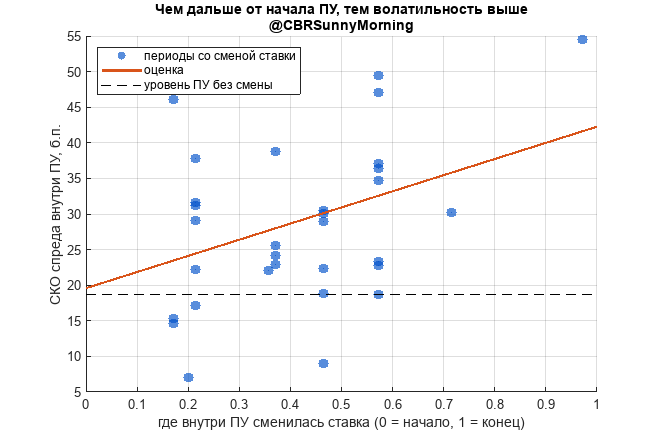

close all

figure('Color','w','Position',[60 60 660 440]);
scatter(C.Pos, C.SdSpread, 60, 'filled','MarkerFaceColor',mymap(1,:),'MarkerFaceAlpha',.65); hold on;
xs = linspace(0,1,20)';
plot(xs, [ones(20,1) xs log(mean(max(C.Step,1)))*ones(20,1)]*rc.b, 'LineWidth',1.6,'Color',[.85 .33 .10]);
plot(xlim, mean(P.SdSpread(~P.HasChange))*[1 1], 'k--');
xlabel('где внутри ПУ сменилась ставка (0 = начало, 1 = конец)');
ylabel('СКО спреда внутри ПУ, б.п.');
legend({'периоды со сменой ставки','оценка','уровень ПУ без смены'},'Location','northwest');
title(["Чем дальше от начала ПУ, тем волатильность выше";LINK_STR]); grid on; box off;

## 6. Тест 1: ротация календаря

Прогоняем прошедшие заседания по календарю (ставим фактические даты в рандомные) - те смотрим влияние ставки на соседние значения РУОНИИ. 

Значение Ratio > Thr95 - событие отлично от случайности, 

ПОЧЕМУ не t-тест: нужен нулевой мир, а не формула. Берём РЕАЛЬНЫЙ календарь заседаний целиком и прокручиваем по истории. Интервалы между заседаниями, их число и растянутость сохраняются; разрушается только привязка к фактическим решениям. Геометрия фона едет вместе с календарём.

ПОЧЕМУ ротация, а не линейный сдвиг: календарь занимает почти всю выборку (первая EffDate — 25-й торговый день, последняя — 24-й с конца), линейных сдвигов остаётся около десятка и минимально достижимое p ~0.08. Ротация идёт внутри диапазона [L0..L1], где у любого заседания помещаются и фон, и ядро, поэтому ни одно псевдо-событие не обрезается. Цена — один шов: на стыке начала и конца один интервал между заседаниями не такой, как в реальном календаре. Из 44 интервалов портится один.

ПОЧЕМУ не набор независимых случайных дат: такой нулевой мир допускает конфигурации, которые реальный график породить не мог, и занижает порог, игнорируя корреляцию псевдо-событий внутри одного розыгрыша.

gm = [masks(1:3), {sched & D.Type~="hold"}, {sched}];
gn = [names(1:3), {'Все со сменой'}, {'Все плановые'}];
res = table('Size',[6 5],'VariableTypes',{'string','double','double','double','double'}, ...
    'VariableNames',{'Group','N','Ratio','Thr95','P'});
for g = 1:5
    [o,pv,th,nRot] = rotationTest(R.LogVol, D.iEff, baseOffs, sched, gm{g}(sched), cfg);
    res(g,:) = {string(gn{g}), sum(gm{g}), exp(o), exp(th), pv};
end
[o6,p6,t6] = rotationTest(R.LogVol, D.iEff, baseOffs, D.Extra, true(sum(D.Extra),1), cfg);
res(6,:) = {"Внеплановые", sum(D.Extra), exp(o6), exp(t6), p6};
disp(res)

         Group         N      Ratio     Thr95         P    
    _______________    __    _______    ______    _________

    "Снижения"         14     3.8881    1.5969            0
    "Повышения"        15     2.0435    1.5929    0.0030395
    "Сохранения"       16    0.88394    1.6562       0.6383
    "Все со сменой"    29     2.7877    1.4019            0
    "Все плановые"     45      1.853    1.3132            0
    "Внеплановые"       4     2.5667     2.443     0.035714



fprintf(['Порог 95%% — КРИТИЧЕСКОЕ значение, а не нулевое: нулевое = 1.00.\n' ...
    'Ротаций %d, минимально достижимое p = %.4f. Написать "p < 0.001" нельзя.\n'], ...
    nRot, 1/nRot);

Порог 95% — КРИТИЧЕСКОЕ значение, а не нулевое: нулевое = 1.00.
Ротаций 1316, минимально достижимое p = 0.0008. Написать "p < 0.001" нельзя.


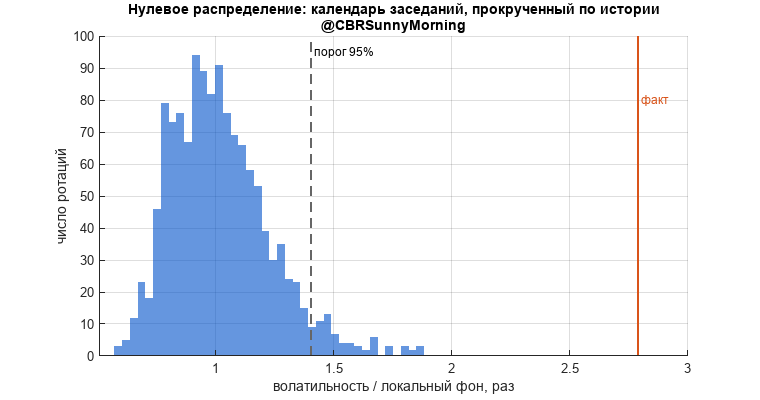


sub = (D.Type~="hold");  sub = sub(sched);
[obs,~,thr,~,null] = rotationTest(R.LogVol, D.iEff, baseOffs, sched, sub, cfg);

close all
figure('Color','w','Position',[60 60 760 400]);
histogram(exp(null),40,'FaceColor',mymap(1,:),'EdgeColor','none'); hold on;
yl = ylim;
plot(exp(thr)*[1 1],yl,'--','Color',[.4 .4 .4],'LineWidth',1.4);
plot(exp(obs)*[1 1],yl,'-','Color',[.85 .33 .10],'LineWidth',2);
text(exp(thr),yl(2)*.95,' порог 95%','FontSize',9);
text(exp(obs),yl(2)*.80,' факт','FontSize',9,'Color',[.85 .33 .10]);
xlabel('волатильность / локальный фон, раз'); ylabel('число ротаций');
title(["Нулевое распределение: календарь заседаний, прокрученный по истории";LINK_STR]);
grid on; box off;

## 8. Тест 2: перестановка ярлыков

Отвечает на ДРУГОЙ вопрос. 

Ротация спрашивает «особенные ли эти даты вообще». 

Перестановка держит даты заседаний неподвижными и тасует между ними типы решений — «особенны ли снижения СРЕДИ заседаний». Расхождение двух тестов информативно: если группа проходит ротацию, но не проходит перестановку, её эффект — это общий эффект заседания, а не что-то специфичное для данного типа решения.

avS = D.AV(sched);
fprintf('\n%-16s %8s %10s %10s\n','Группа','факт','p(ротация)','p(перест.)');

Группа               факт p(ротация) p(перест.)


for g = 1:4
    m = gm{g}(sched);  o = mean(avS(m),'omitnan');
    nullP = nan(cfg.nPerm,1);
    for k = 1:cfg.nPerm
        pk = randperm(numel(avS), sum(m));
        nullP(k) = mean(avS(pk),'omitnan');
    end
    fprintf('%-16s %8.2f %10.4f %10.4f\n', gn{g}, exp(o), res.P(g), mean(nullP>=o));
end

Снижения             3.89     0.0000     0.0016
Повышения            2.04     0.0030     0.3629
Сохранения           0.88     0.6383     0.9983
Все со сменой        2.79     0.0000     0.0013


## 9. Внеплановые заседания — только поштучно

N = 4: СКО нулевого распределения 0.57 в логах против 0.16 у сорока пяти плановых — ровно sqrt(45/4). Отсюда порог около 2.4x вместо 1.3x, и это не лечится настройкой окна. 

У 08.04.2022 испорчен сам фон: его окно приходится на март 2022 г., самый турбулентный отрезок выборки. 

Шаги внеплановых (+1050, -300, -300, +350) сопоставимы лишь с одним плановым решением, так что «внеплановость» и «огромный шаг» в этой выборке разделить невозможно в принципе.

ex = find(D.Extra);
X = table('Size',[numel(ex) 6],'VariableTypes', ...
    {'string','double','double','double','double','double'}, ...
    'VariableNames',{'Date','StepBp','BaseBp','EventBp','Ratio','LocalP'});
for k = 1:numel(ex)
    j = D.iEff(ex(k));
    b = mean(R.LogVol(clip(j+baseOffs{ex(k)},height(R))),'omitnan');
    e = mean(R.LogVol(clip(j+cfg.hit,height(R))),'omitnan');
    X(k,:) = {string(datestr(D.Date(ex(k)),'dd.mm.yyyy')), D.Delta(ex(k)), ...
        exp(b), exp(e), exp(e-b), localP(R.LogVol,j,cfg.hit,60)};
end
disp(X)

        Date        StepBp    BaseBp    EventBp     Ratio      LocalP 
    ____________    ______    ______    _______    _______    ________

    "28.02.2022"     1050     6.4542    50.331      7.7982    0.016529
    "08.04.2022"     -300     8.6218    4.1602     0.48252     0.61983
    "26.05.2022"     -300     2.0099    9.1855        4.57     0.42149
    "15.08.2023"      350      5.595    14.121      2.5239     0.10744



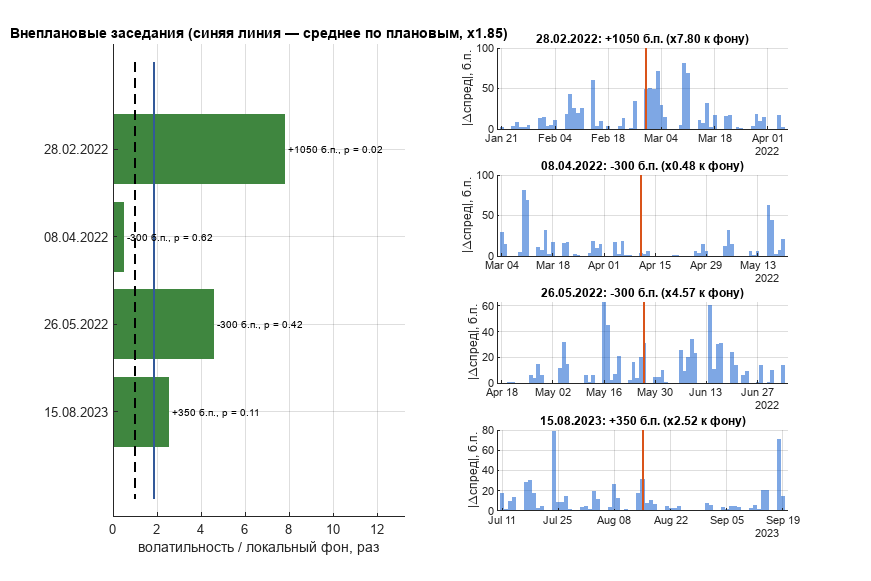


figure('Color','w','Position',[60 60 1050 700]);
subplot(numel(ex),2,1:2:2*numel(ex));
barh(X.Ratio,'FaceColor',mymap(3,:),'EdgeColor','none'); hold on;
mS = exp(mean(D.AV(sched),'omitnan'));
plot([1 1],[0 numel(ex)+1],'k--','LineWidth',1.2);
plot([mS mS],[0 numel(ex)+1],'-','Color',[.20 .35 .60],'LineWidth',1.5);
set(gca,'YTick',1:numel(ex),'YTickLabel',cellstr(X.Date),'YDir','reverse');
for k = 1:numel(ex)
    text(X.Ratio(k)+.15,k,sprintf('%+.0f б.п., p = %.2f',X.StepBp(k),X.LocalP(k)),'FontSize',8);
end
xlim([0 max(X.Ratio)*1.7]); grid on; box off;
xlabel('волатильность / локальный фон, раз');
title(sprintf('Внеплановые заседания (синяя линия — среднее по плановым, x%.2f)',mS));
for k = 1:numel(ex)
    subplot(numel(ex),2,2*k);
    j = D.iEff(ex(k));  rg = max(1,j-25):min(height(R),j+25);
    bar(R.Date(rg),R.Vol(rg),1,'FaceColor',mymap(1,:),'FaceAlpha',0.5,'EdgeColor','none'); hold on;
    yl = ylim;
    plot([R.Date(j) R.Date(j)],yl,'-','Color',[.85 .33 .10],'LineWidth',1.5);
    ylim(yl); ylabel('|\Deltaспред|, б.п.'); grid on; box off;
    title(sprintf('%s: %+.0f б.п. (x%.2f к фону)',X.Date(k),X.StepBp(k),X.Ratio(k)),'FontSize',9);
end

## 10. Единая шкала: эффект против размера шага

Корректный способ поставить внеплановые в общий ряд. Вместо сравнения групп смотрим, ложатся ли ВСЕ 49 заседаний на одну зависимость «эффект от `шага`». Тогда внеплановые — не отдельная категория, а просто точки с большим `Δставки`, и вопрос становится проверяемым: лежат они на общей линии или выше неё.

u  = ~isnan(D.AV);
Xs = [ones(sum(u),1), log(max(abs(D.Delta(u)),1)), double(D.Extra(u))];
rs = ols(D.AV(u), Xs, {'const','log|шаг ставки|','I(внеплановое)'});
printOLS(rs);

Регрессор                коэф.    ст.ош.        t        p
const                   -0.163     0.327    -0.50   0.6203
log|шаг ставки|          0.277     0.083     3.33   0.0017
I(внеплановое)          -0.570     0.566    -1.01   0.3197
R^2 = 0.226, N = 49


fprintf(['Если коэффициент при I(внеплановое) не отличим от нуля, значит\n' ...
    'внеплановые ведут себя как плановые с таким же шагом, и отдельной\n' ...
    'категории не нужно.\n']);

Если коэффициент при I(внеплановое) не отличим от нуля, значит
внеплановые ведут себя как плановые с таким же шагом, и отдельной
категории не нужно.


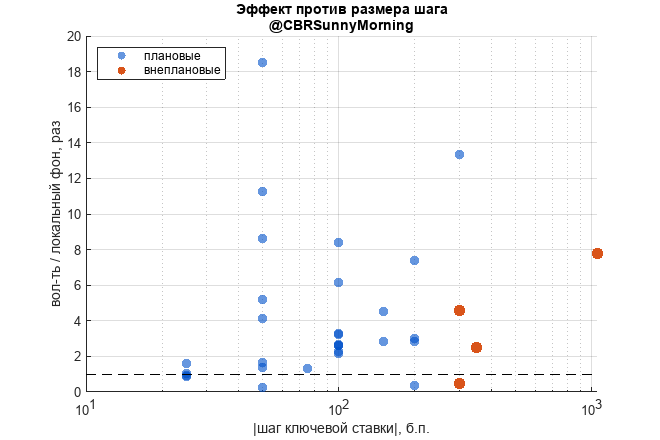


figure('Color','w','Position',[60 60 660 440]);
scatter(abs(D.Delta(sched&u)), exp(D.AV(sched&u)),55,'filled','MarkerFaceColor',mymap(1,:),'MarkerFaceAlpha',.6); hold on;
scatter(abs(D.Delta(D.Extra&u)), exp(D.AV(D.Extra&u)),80,'filled','MarkerFaceColor',[.85 .33 .10]);
set(gca,'XScale','log'); plot(xlim,[1 1],'k--');
xlabel('|шаг ключевой ставки|, б.п.'); ylabel('вол-ть / локальный фон, раз');
legend({'плановые','внеплановые'},'Location','northwest');
title(["Эффект против размера шага";LINK_STR]); grid on; box off;

## 11. Из чего состоит всплеск: неполное проведение ставки

Профиль показал, что эффект сидит в одном дне. Проверяем, не механика ли это. Если бы RUONIA мгновенно перескакивала на новый уровень, спред бы не дрогнул; если бы не двигалась вовсе, спред прыгнул бы ровно на -Δставки. Коэффициент между -1 и 0 показывает, какую долю шага рынок НЕ отыгрывает в первый день. Это и есть эффект стратегий усреднения резервов — описывать его надо как неполное проведение ставки, а не как «рост волатильности».

ch = sched & D.Type~="hold";
d0 = R.Spread(D.iEff(ch)) - R.Spread(D.iEff(ch)-1);
dk = D.Delta(ch);
bb = [ones(numel(dk),1) dk] \ d0;
fprintf('\nΔспреда(0) = %.2f * Δставки %+.1f   (корр %.2f)\n', bb(2), bb(1), corrAR(d0,dk));


Δспреда(0) = -0.31 * Δставки +1.9   (корр -0.70)


fprintf('  -1.00 = RUONIA неподвижна, 0.00 = мгновенная подстройка\n');

  -1.00 = RUONIA неподвижна, 0.00 = мгновенная подстройка


fprintf('|Δспреда| в день 0: %.1f б.п. при среднем |шаге| %.0f б.п. (%.0f%% шага)\n', ...
    mean(abs(d0)), mean(abs(dk)), 100*mean(abs(d0))/mean(abs(dk)));

|Δспреда| в день 0: 43.3 б.п. при среднем |шаге| 99 б.п. (44% шага)


fprintf('|Δспреда| в день ЗАСЕДАНИЯ (ставка ещё старая): %.1f б.п., обычный день: %.1f б.п.\n', ...
    mean(abs(R.Spread(D.iAnn(ch))-R.Spread(D.iAnn(ch)-1))), mean(R.Vol,'omitnan'));

|Δспреда| в день ЗАСЕДАНИЯ (ставка ещё старая): 10.3 б.п., обычный день: 11.2 б.п.


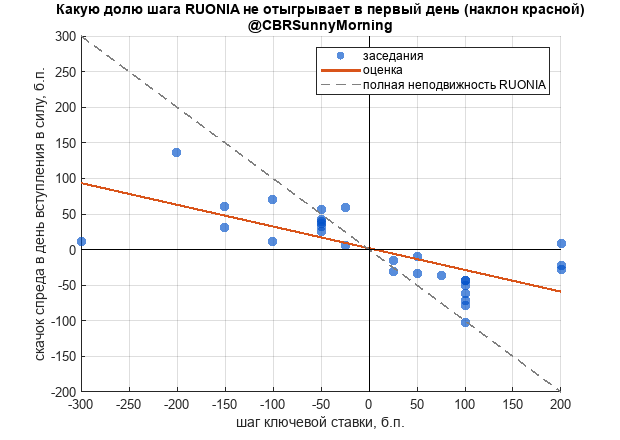

close all

figure('Color','w','Position',[60 60 620 440]);
scatter(dk,d0,55,'filled','MarkerFaceColor',mymap(1,:),'MarkerFaceAlpha',.65); hold on;
xs = linspace(min(dk),max(dk),20);
plot(xs, bb(1)+bb(2)*xs,'LineWidth',1.6,'Color',[.85 .33 .10]);
plot(xs,-xs,'--','Color',[.5 .5 .5],'LineWidth',1.2);
plot(xlim,[0 0],'k-'); plot([0 0],ylim,'k-');
xlabel('шаг ключевой ставки, б.п.'); ylabel('скачок спреда в день вступления в силу, б.п.');
legend({'заседания','оценка','полная неподвижность RUONIA'},'Location','northeast');
title(["Какую долю шага RUONIA не отыгрывает в первый день (наклон красной)";LINK_STR]); grid on; box off;

## 12. Сюрприз

Простое сравнение «сюрприз есть / нет» вводит в заблуждение: сюрпризы случаются чаще там, где ставка меняется. 

Нужна двумерная таблица, а затем регрессия, разделяющая два эффекта.

S = D(sched,:);  S.changed = S.Delta~=0;  S.hasSur = S.AbsSurprise>0;
fprintf('\n%-14s %-10s %4s %10s\n','Ставка','Сюрприз','N','x к фону');

Ставка         Сюрприз       N   x к фону


for c = [true false]
    for s2 = [true false]
        m = S.changed==c & S.hasSur==s2;
        if ~any(m), continue; end
        fprintf('%-14s %-10s %4d %10.2f\n', ternary(c,'изменилась','не менялась'), ...
            ternary(s2,'есть','нет'), sum(m), exp(mean(S.AV(m),'omitnan')));
    end
end

изменилась     есть         16       2.41
изменилась     нет          13       3.33
не менялась    есть          1       0.58
не менялась    нет          15       0.91


u2 = ~isnan(S.AV) & ~isnan(S.AbsSurprise);
X2 = [ones(sum(u2),1), double(S.changed(u2)), S.AbsSurprise(u2)/100];
r2 = ols(S.AV(u2), X2, {'const','ставка изменилась','|сюрприз|, п.п.'});
printOLS(r2);

Регрессор                коэф.    ст.ош.        t        p
const                   -0.120     0.349    -0.34   0.7322
ставка изменилась        1.154     0.390     2.96   0.0051
|сюрприз|, п.п.         -0.025     0.263    -0.09   0.9261
R^2 = 0.198, N = 45


fprintf('Контрфактика: факт x%.2f, все сюрпризы обнулены x%.2f, без смены ставки x%.2f\n', ...
    exp(mean(X2*r2.b)), exp(mean([X2(:,1:2) zeros(sum(u2),1)]*r2.b)), ...
    exp(mean([X2(:,1) zeros(sum(u2),2)]*r2.b)));

Контрфактика: факт x1.85, все сюрпризы обнулены x1.86, без смены ставки x0.89


## 13. Где сидит всплеск: объявление или вступление в силу

У внеплановых эти даты совпадают, у плановых разнесены на 3 календарных дня, а с 2027 г. станут на 5. 

Прямая проверка логики ЦБ.

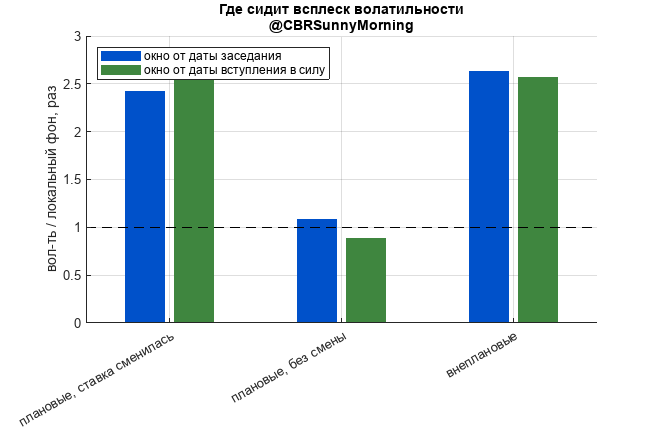

g3  = {sched & D.Type~="hold", sched & D.Type=="hold", D.Extra};
lab = {'плановые, ставка сменилась','плановые, без смены','внеплановые'};
V = zeros(3,2);
for i = 1:3
    V(i,1) = exp(mean(D.AVann(g3{i}),'omitnan'));
    V(i,2) = exp(mean(D.AV(g3{i}),'omitnan'));
end

close all
figure('Color','w','Position',[60 60 660 430]);
b = bar(V,'EdgeColor','none'); 
b(1).FaceColor = mymap(1,:);b(2).FaceColor = mymap(3,:);
hold on; plot(xlim,[1 1],'k--');
set(gca,'XTickLabel',lab); ylabel('вол-ть / локальный фон, раз');
legend({'окно от даты заседания','окно от даты вступления в силу'},'Location','northwest');
title(["Где сидит всплеск волатильности";LINK_STR]); grid on; box off;

## 15. Сводка

fprintf('\n===== ИТОГ =====\n');
inW = false(height(R),1);


===== ИТОГ =====


for i = 1:height(D)
    if ~isnan(D.iEff(i)), inW(clip(D.iEff(i)+cfg.hit,height(R))) = true; end
end
fprintf('|Δспреда|: в окнах заседаний %.1f б.п., вне окон %.1f б.п.\n', ...
    mean(R.Vol(inW),'omitnan'), mean(R.Vol(~inW),'omitnan'));
fprintf('Смена ставки:      x%.2f  (ротация p = %.4f)\n', res.Ratio(4), res.P(4));

|Δспреда|: в окнах заседаний 18.7 б.п., вне окон 10.3 б.п.


fprintf('Сохранение ставки: x%.2f  (порог %.2f не пройден)\n', res.Ratio(3), res.Thr95(3));

Смена ставки:      x2.79  (ротация p = 0.0000)


fprintf('Сюрприз:           коэффициент %+.3f, t = %.2f\n', r2.b(3), r2.t(3));

Сохранение ставки: x0.88  (порог 1.66 не пройден)


fprintf('Проведение ставки: рынок не отыгрывает %.0f%% шага в первый день\n', 100*abs(bb(2)));

Сюрприз:           коэффициент -0.025, t = -0.09


## Локальные функции

function s = stepSeries(cal, chg, val)

Проведение ставки: рынок не отыгрывает 31% шага в первый день


s = nan(numel(cal),1);
[chg,o] = sort(chg);  val = val(o);
for i = 1:numel(chg), s(cal >= chg(i)) = val(i); end
s(cal < chg(1)) = val(1);
end

function idx = mapToCal(t, cal)
% Первый торговый день >= t. Нужен, потому что дата вступления в силу может
% попасть на праздник (например 01.05.2023).
idx = nan(numel(t),1);
for i = 1:numel(t)
    j = find(cal >= t(i),1,'first');
    if ~isempty(j), idx(i) = j; end
end
end

function f = periodPos(d, M)
% Доля периода усреднения, пройденная к дате d: 0 = первый день, 1 = последний.
f = nan(numel(d),1);
for i = 1:numel(d)
    k = find(M.Start <= d(i) & M.End >= d(i), 1);
    if isempty(k), continue; end
    f(i) = (days(d(i) - M.Start(k)) + 1) / (days(M.End(k) - M.Start(k)) + 1);
end
end

function [offs, nUsed] = baselineOffsets(iEv, allE, cfg, n)
% Смещения фона для каждого заседания: [far..near] минус дни влияния ЛЮБОГО
% другого заседания. Хранятся как СМЕЩЕНИЯ, поэтому при ротации календаря
% едут вместе с ним и геометрия фона в нулевом мире совпадает с фактической.
offs = cell(numel(iEv),1);  nUsed = zeros(numel(iEv),1);
for i = 1:numel(iEv)
    j = iEv(i);
    if isnan(j), offs{i} = []; continue; end
    far = cfg.far;
    while true
        w = (j+far):(j+cfg.near);
        bad = false(size(w));
        for k = 1:numel(allE)
            if allE(k)==j, continue; end
            bad = bad | (w >= allE(k)+cfg.otherWin(1) & w <= allE(k)+cfg.otherWin(end));
        end
        w = w(~bad & w>=1 & w<=n);
        if numel(w) >= cfg.minBase || far <= -90, break; end
        far = far - 5;
    end
    offs{i} = w - j;  nUsed(i) = numel(w);
end
end

function [AV, avHit] = avEvents(vol, iEv, offs, tau, hit)
n = numel(vol);
AV = nan(numel(iEv),numel(tau));  avHit = nan(numel(iEv),1);
for i = 1:numel(iEv)
    j = iEv(i);
    if isnan(j) || isempty(offs{i}), continue; end
    w = clip(j+offs{i},n);
    if isempty(w), continue; end
    b  = mean(vol(w),'omitnan');
    ie = j+tau;  ok = ie>=1 & ie<=n;
    AV(i,ok) = vol(ie(ok))' - b;
    ih = clip(j+hit,n);
    if ~isempty(ih), avHit(i) = mean(vol(ih),'omitnan') - b; end
end
end

function [obs, p, thr, nRot, null] = rotationTest(vol, iEv, offs, calMask, sub, cfg)
% Ротация календаря внутри диапазона [L0..L1], где у любого заседания
% помещаются и фон, и ядро — поэтому ни одно псевдо-событие не обрезается.
n    = numel(vol);
idx  = iEv(calMask);  ofs = offs(calMask);  idx = idx(:);
deep = min(cellfun(@(o) min([o 0]), ofs));
L0   = 1 - deep;
L1   = n - max(cfg.hit);
L    = L1 - L0 + 1;
rots = 0:L-1;
rots = rots(min(rots, L-rots) >= cfg.minShift);
null = nan(numel(rots),1);
for k = 1:numel(rots)
    pos = L0 + mod(idx - L0 + rots(k), L);
    null(k) = mean(evalAt(vol, pos(sub), ofs(sub), cfg.hit, n),'omitnan');
end
obs  = mean(evalAt(vol, idx(sub), ofs(sub), cfg.hit, n),'omitnan');
p    = mean(null >= obs);
thr  = prctile_(null, 95);
nRot = numel(rots);
end

function a = evalAt(vol, pos, ofs, hit, n)
a = nan(numel(pos),1);
for i = 1:numel(pos)
    w = pos(i)+ofs{i};  h = pos(i)+hit;
    if isempty(w) || min(w)<1 || max(w)>n || min(h)<1 || max(h)>n, continue; end
    a(i) = mean(vol(h),'omitnan') - mean(vol(w),'omitnan');
end
end

function p = localP(vol, idx, hit, half)
% Локальный односторонний p для ОДНОГО события: доля позиций окна той же
% ширины в окрестности +-half дней, где волатильность была не ниже.
n = numel(vol);
lo = max(1-min(hit), idx-half);  hi = min(n-max(hit), idx+half);
if hi <= lo, p = NaN; return; end
c = lo:hi;  st = nan(numel(c),1);
for j = 1:numel(c), st(j) = mean(vol(c(j)+hit),'omitnan'); end
p = mean(st >= mean(vol(idx+hit),'omitnan'));
end

function r = ols(y, X, names)
n = size(X,1); k = size(X,2);
b = X\y;  u = y - X*b;  A = inv(X'*X); %#ok<MINV>
V = A*((X.*u)'*(X.*u))*A * n/(n-k);          % робастные ошибки Уайта
se = sqrt(diag(V));  t = b./se;
r = struct('b',b,'se',se,'t',t,'p',betainc((n-k)./((n-k)+t.^2),(n-k)/2,0.5), ...
    'n',n,'R2',1-sum(u.^2)/sum((y-mean(y)).^2),'names',{names});
end

function printOLS(r)
fprintf('\n%-20s %9s %9s %8s %8s\n','Регрессор','коэф.','ст.ош.','t','p');
for i = 1:numel(r.b)
    fprintf('%-20s %9.3f %9.3f %8.2f %8.4f\n', r.names{i}, r.b(i), r.se(i), r.t(i), r.p(i));
end
fprintf('R^2 = %.3f, N = %d\n', r.R2, r.n);
end

function ix = clip(ix, n)
ix = ix(:);  ix = ix(ix>=1 & ix<=n);
end

function c = corrAR(a, b)
a = a-mean(a); b = b-mean(b);  c = (a'*b)/sqrt((a'*a)*(b'*b));
end

function q = prctile_(x, pc)
x = sort(x(~isnan(x)));
if isempty(x), q = NaN; return; end
q = x(max(1, ceil(numel(x)*pc/100)));
end

function s = ternary(c, a, b)
if c, s = a; else, s = b; end
end